## Método Runge - Kutta5

Para una ecuación diferencial de 2do orden

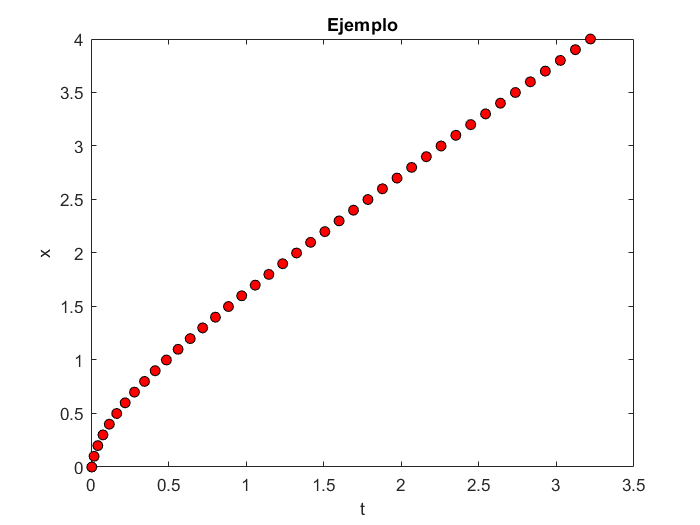

clear; clc;

h=0.1;
t=0;
x=0;

k1=@(t) h*(t/sqrt(1+power(t,2))); %Cambiar la expresión de acuerdo a la función analizada
k2=@(t) h*((t+h)/sqrt(1+(power(t+h,2)))); %Cambiar la expresión de acuerdo a la función analizada

for t=0:0.1:4
    delta_x = (k1(t) + k2(t))/2;
    x = x + delta_x;
    plot(x,t,'ko','MarkerFaceColor','r');
    hold on;
end

title("Ejemplo");
xlabel("t");
ylabel("x");
hold off;